# Trajectories and motion planning

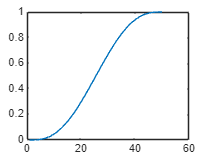

% The toolbox function tpoly generates a quintic polynomial trajectory:
clear; clc;
s = tpoly(0, 1, 50); % Creates a 50x1 vector containing values varying smoothly from 0 to 1 in 50 time steps which we can plot)
plot(s)

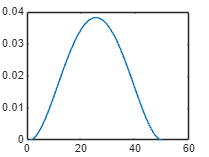


% Corresponding velocity and acceleration can be returned
[s, sd, sdd] = tpoly(0,1,50);
plot(sd)

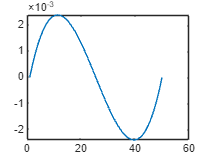

plot(sdd)

In the above, tpoly creates a fifth order polynomial and gives us a plot of the values of distance, velocity and acceleration with distance ranging from 0 to 1, with 50 time steps.

In this scheme, initial and final velocity and acceleration are all defaulted to zero. We can set these to non-zero values as shown below.

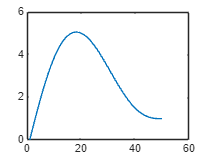

clc; clear;
[s, sd, sdd] = tpoly(0, 1, 50, 0.5, 0);
% Here velocity comes from 0.5 and ends at 0
plot(s)

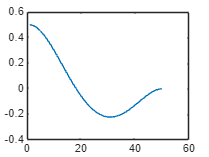

plot(sd)

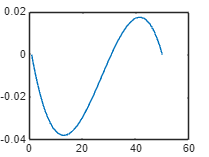

plot(sdd)

% As seen above, non-zero initial velocities cause an overshoot
% Also, velocity peaks at t = 25 and the rest of the time the velocity is
% low


## Hybrid trajectory plan

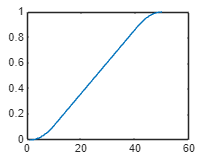

clc; clear;
% Improving the trajectory plan is a hybrid technology\
% Linear segments with parabolic blends
[s, sd, sdd] = lspb(0,1,50, 0.025); % The fourth value is the velocity of the linear segment
plot(s)

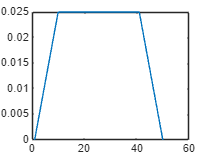

plot(sd)

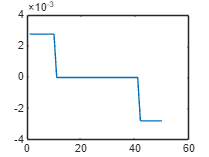

plot(sdd)

## Multi-Dimensional Case

% Moving from a point in the coordinate frame:
% From (0,2) to (1, -1) in 50 steps can be found using

x = mtraj(@tpoly, [0 2], [1 -1], 50);
x = mtraj(@lspb, [0 2], [1 -1], 50);
% The above basically does the lspb and tpoly independently for both x and
% y, and gives these values as in a 50 x 2 matrix

% For a three dimensional problem, we convert the orientation to a vectorrr
% before using it.
T = trotx(rad2deg(pi/2)) * transl(1,2,3)

T =      1     0     0     1
     0     0    -1    -3
     0     1     0     2
     0     0     0     1


x = [transl(T); tr2rpy(T)']

x =     1.0000
   -3.0000
    2.0000
    1.5708
         0
         0


## Multi-segment trajectories: containing via points

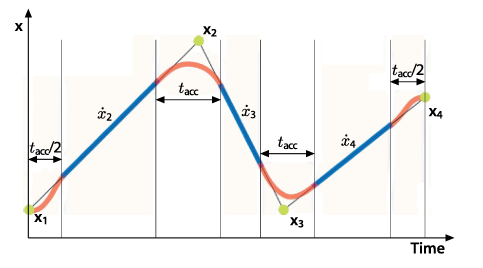

The motion here is uniform and is similar to lspb but we use quintic polyhnomials [higher order polynoms].

We will use the toolbox function mstraj for this. 

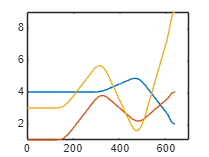

% Two axis motion with four points can be generated by:
via = [4,1,3; 4,4,6; 5,2,1; 2,4,9];
q = mstraj(via, [2,1,4], [], [4,1,3], 0.05, 4);
plot(q)

% In the above, we provide the follwing arguments:
% - list of via points, one row per point [x2-xn]
% - a vector of maximum speeds per axis [x2'-xn']
% - a vector of durations for each segment
% - initial axis coordinates [x1]
% - sample interval
% - acceleration time [tacc in the figure]

% Above can work for position in x y z but not so good for orientation.
% Orientation is displayed below


## Cartesian motion (Motion between two poses)

% This involves change between both orientation and position
% The initial and final poses will be represented as homogenous
% transformations

T0 = transl(0.4, 0.2, 0) * trotx(rad2deg(pi));
T1 = transl(-0.4, -0.2, 0.3) * troty(rad2deg(pi/2)) * trotz(rad2deg(-pi/2))

T1 =          0         0    1.0000   -0.4000
   -1.0000         0         0   -0.2000
         0   -1.0000         0    0.3000
         0         0         0    1.0000


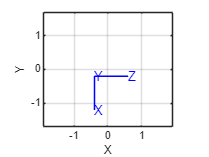


% trinterp gives a normalized interpolation between the two points
trinterp(T0, T1, 0.5); % Gives the mid pose. [0.5 is mid, 0 is start, and 1 is final

% In above, the translation is linearly interpolated while the rotation is
% sperically interpolated

% To calculate a trajectory between the two poses in 50 steps we do:
Ts = trinterp(T0, T1, [0:49]/49); % a 4x4x50 matrix
tranimate(T0, Ts)


% This is made better by:
Ts = trinterp(T0, T1, lspb(0,1, 50) ); %lspb gives a nice parabolic blend in velocity
tranimate(T0, Ts)


% Shorthand for the above is ctraj
Ts = ctraj(T0, T1, 50); % Initial pose, final pose, steps
